A = [10, 20, 30;
     40, 50, 60;
     70, 80, 90]

A =     10    20    30
    40    50    60
    70    80    90


C = num2cell(A)%pavercia skaicius i cele

C = 3×3 cell array
    {[10]}    {[20]}    {[30]}
    {[40]}    {[50]}    {[60]}
    {[70]}    {[80]}    {[90]}


length(A);%eiluciu ilgis
isreal(A);
cell2mat(C);%atgal sugrazina(A)

ans =     10    20    30
    40    50    60
    70    80    90


clear
close all

A = [10, 20, 30;
     40, 50, 60;
     70, 80, 90];

isreal(A);%skaiciai realieji ant matricos

C = num2cell(A);

C{1, 2} = [];%stulpelis, eilute = 20
C{3, 1} = [];%= 70

length(C);

cellfun(@isempty, C)%cellfun pertikrina visa cele

ans = 3×3 logical array
   0   1   0
   0   0   0
   1   0   0


%po kiekviena skaiciu, isempty patikrina tuscias vietas

m = 3

n = 3

     2     5    10
     3     6    11
     4     7    12



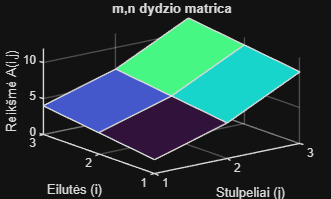

Įvesti vienodi m ir n (m = n). Darbas baigtas!


clear
close all
while true%iki kol tiesa
    m = input('Įveskite eilučių skaičių m: ')
    n = input('Įveskite stulpelių skaičių n: ')
    A = zeros(m, n);%matrica pagal m ir n ir visi nuliui
    for i = 1:m
        for j = 1:n
            A(i, j) = i + j^2;
        end
    end
    disp(A);
    figure;
    surf(A);
    title('m,n dydzio matrica');
    xlabel('Stulpeliai (j)');
    ylabel('Eilutės (i)');
    zlabel('Reikšmė A(i,j)');
    colormap('turbo')
    if m == n
        disp('Įvesti vienodi m ir n (m = n). Darbas baigtas!');
        break;
    else
        disp('m ir n nelygūs – kartojame iš naujo...');
    end
end

clear
close all
masyvas1 = [];%tusti masyvai
masyvas2 = [];
kiek_is_eiles = 0;


while true
    sk1 = round(rand * 5);%generuojami skaiciai rand-random
    sk2 = round(rand * 7);%round suapvalinami
    
    masyvas1 = cat(1, masyvas1, sk1);
    masyvas2 = cat(1, masyvas2, sk2);
    
    if sk2 > sk1%tikrinama
        kiek_is_eiles = kiek_is_eiles + 1;
    else
        kiek_is_eiles = 0;
    end
    
    if kiek_is_eiles == 3%kai ciklas pasieks 3 sulus ciklas
        disp('Antrasis skaicius buvo didesnis 3 kartus is eiles');
        break;
    end
end

Antrasis skaicius buvo didesnis 3 kartus is eiles


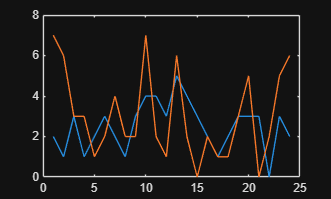

bendras_masyvas = cat(2, masyvas1, masyvas2);
plot(bendras_masyvas)